# Impairments

## DC offset

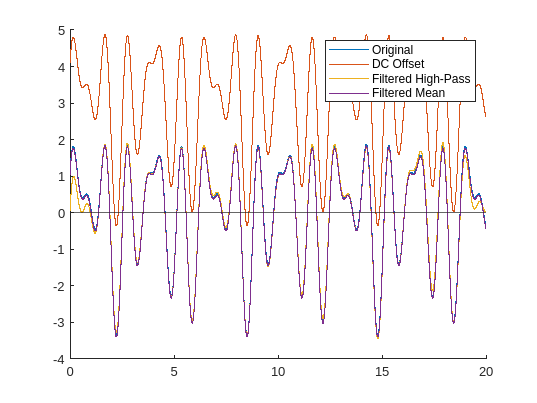

clf
hold on

Fs = 1e3;
delta_t = 1/Fs;
time_duration = 20;
t = 0:delta_t:time_duration;
signal_tx = 0.8*sin(2*t) + 1.5*sin(5*t) + 1.1 * sin(7*t+pi/2);

plot(t, signal_tx, DisplayName='Original');
yline(0, HandleVisibility='off');

dc_offset = 3;

signal_rx = dc_offset + signal_tx;
plot(t, signal_rx, DisplayName='DC Offset');

signal_rx_fixed_high_pass = highpass(signal_rx, 0.2, Fs);
plot(t, signal_rx_fixed_high_pass, DisplayName='Filtered High-Pass');

signal_rx_fixed_mean = signal_tx - mean(signal_tx);
plot(t, signal_rx_fixed_mean, DisplayName='Filtered Mean');

legend
hold off

## IQ imbalance

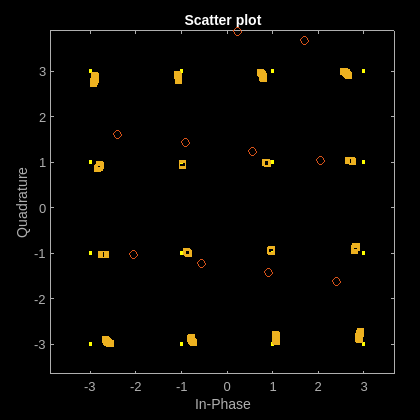

amplitude_imbalance = -5;
phase_imbalance = 15;


original_constellation = qammod(randi([0 15], 2e4 , 1), 16);

scat = scatterplot(original_constellation);
hold on

constellation_Imbalanced = iqimbal(original_constellation, amplitude_imbalance, phase_imbalance);
scatterplot(constellation_Imbalanced, 1, 0, 'o', scat);

iqcomp = comm.IQImbalanceCompensator;

constellation_compensated = iqcomp(constellation_Imbalanced);
scatterplot(constellation_compensated(1e4:end), 1, 0, 's', scat);